Climb rate

% Requirments
zeta = 1;
ts2 = 3;
wn = 4/(zeta*ts2)

wn = 1.3333


Ts_climb = 1/(20*wn)

Ts_climb = 0.0375


p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
     -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =    -1.3333
   -1.3333


p_z_want = exp(p_s_want*Ts_climb)

p_z_want =     0.9512
    0.9512


Climb is controllable


kp_climb =     0.3740  144.2470


ki_climb = 2.9143

Nbar_climb = 26.2289

C_climb =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 75.4, Ki = 19.5, Ts = 0.0375
 
Sample time: 0.0375 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.1550
           PhaseMargin: 60.0000


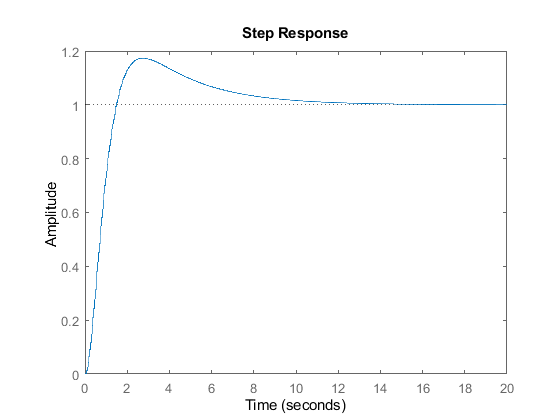


% Plant
A_climb = [-1/t_P,  0;
            1/m(1), 0];
b_climb = [1/t_P; 0];
c_climb = [0, 1];
d_climb = 0;

sysC = ss(A_climb,b_climb,c_climb,d_climb);
sysD_climb = c2d(sysC,Ts_climb,'zoh');
F = sysD_climb.A;
G = sysD_climb.B;

% Controllability
U_test = ctrb(F,G);
if det(U_test) == 0
    disp('Climb is NOT controllable')
else
    disp('Climb is controllable')
    
    F_bar = [F,zeros(2,1); c_climb*F, 1];
    g_bar = [G;c_climb*G];

    kclimb = acker(F_bar,g_bar,[p_z_want;0.9]);
    kp_climb = kclimb(1:2)
    ki_climb = kclimb(3)
    Nbar_climb = (ki_climb*0.9)/(1-0.9)
    
    [C_climb,info] = pidtune(sysD_climb,'PI')
    step(feedback(C_climb*sysD_climb,1))
end

Altitude

Ts_alt = 1/50;
% Plant
A_alt = [-1/t_P,  0, 0;
          1/m(1), 0, 0;
          0     ,-1, 0];
b_alt = [1/t_P; 0; 0];
c_alt = [0, 0, 1];
d_alt = 0;

sysC = ss(A_alt,b_alt,c_alt,d_alt);
sysD = c2d(sysC,Ts_alt,'zoh');
F = sysD.A;
G = sysD.B;

% Controllability
U_test = ctrb(F,G);
if det(U_test) == 0
    disp('Alt is NOT controllable')
else
    disp('Alt is controllable')
    Q1 = [0, 0, 0;
          0, 0, 0;
          0, 0, 1];
    Q2 = 0.01;
    k_alt = lqr(sysD,Q1,Q2)
end

Alt is controllable


k_alt =     0.1391   38.0775   -9.9444
